Choose Data Subset of Interest

dataSubset = "tubes";

% Creates a Datastore to store all images of specified type

fileLoc = sprintf("MPDD/%s", dataSubset);
ds = datastore(fileLoc,"IncludeSubfolders",true);
numFiles = numel(ds.Files);
disp("Number of Files: " + numFiles);

Number of Files: 292



% Image processing
% Load image and create grayscale version, display both side by side
img = readimage(ds, 100);
imgGS = rgb2gray(img);

disp("Color and Grayscale")

Color and Grayscale


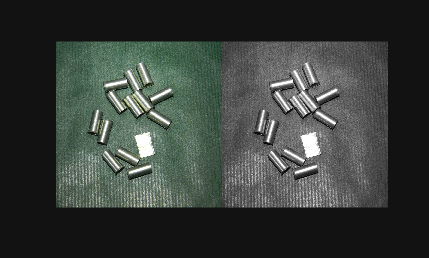

imshowpair(img, imgGS, "montage");


% Extract the Green and Blue layers and use it as a mask to remove the
% background for better classification. 

% TO-DO: Find a way to determine which layer is better without having to perform both operations. From
% what I can see (Ryan), there appears to be a more significant tail in the
% mask that is better for removing the background, but I am unsure of how
% to remove it
SE = strel("diamond",15);

imgG = img(:,:,2); 
imgGOpen = imopen(imgG, SE);
disp("Green distribution");

Green distribution


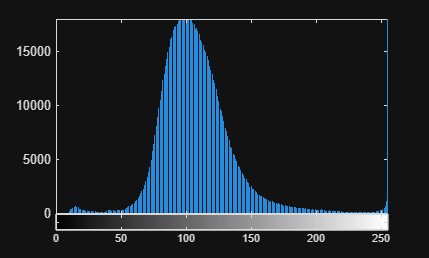

imhist(imgG);


imgB = img(:,:,3);
imgBOpen = imopen(imgB, SE);
disp("Blue distribution");

Blue distribution


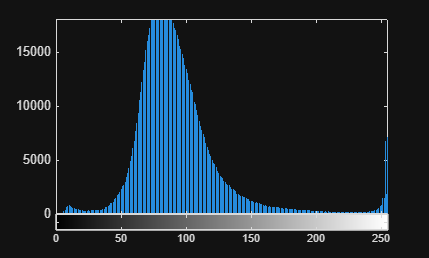

imhist(imgB);

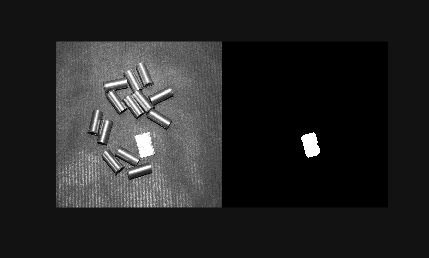


maskG = imbinarize(imgGOpen, "global"); % background is bright (1s)
imshowpair(imgG, maskG, "montage");

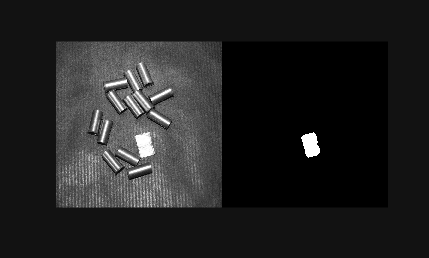

maskB = imbinarize(imgBOpen); % background is dark (0s)
imshowpair(imgB, maskB, "montage");


% Use the Green Layer's mask
mask = maskG;

imgNoBG = img .* cast(~mask, class(img));
imgGSNoBG = imgGS;
imgGSNoBG(mask) = 0;

disp("Color and Grayscale (No Background, Green)")

Color and Grayscale (No Background, Green)


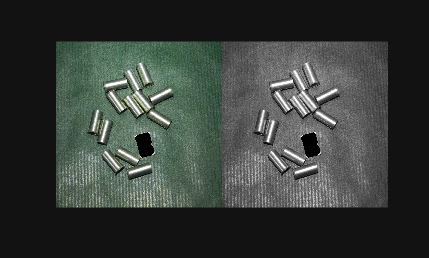

imshowpair(imgNoBG, imgGSNoBG, "montage");


% Use the Blue Layer's mask
mask = ~maskB;

imgNoBG = img .* cast(~mask, class(img));
imgGSNoBG = imgGS;
imgGSNoBG(mask) = 0;

disp("Color and Grayscale (No Background, Blue)")

Color and Grayscale (No Background, Blue)


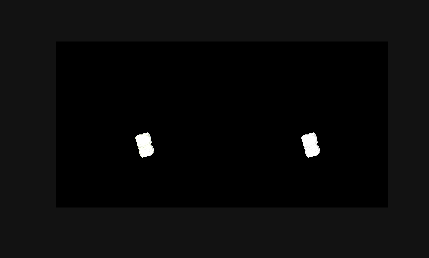

imshowpair(imgNoBG, imgGSNoBG, "montage");